clear all;
%carico il dataset
load("data.mat")
input=[time,pw]

input =          0  144.4852
    0.0500  144.4852
    0.1000  144.4852
    0.1500  144.4852
    0.2000  144.4852
    0.2500  144.4852
    0.3000  170.8863
    0.3500  170.8863
    0.4000  170.8863
    0.4500  170.8863


%eseguo il simulink che ci è stato dato
out1=sim("model.mdl")

i = 1

out1 =          0
    0.0000
    0.0000
    0.0001
    0.0003
    0.0016
    0.0079
    0.0172
    0.0232
    0.0292


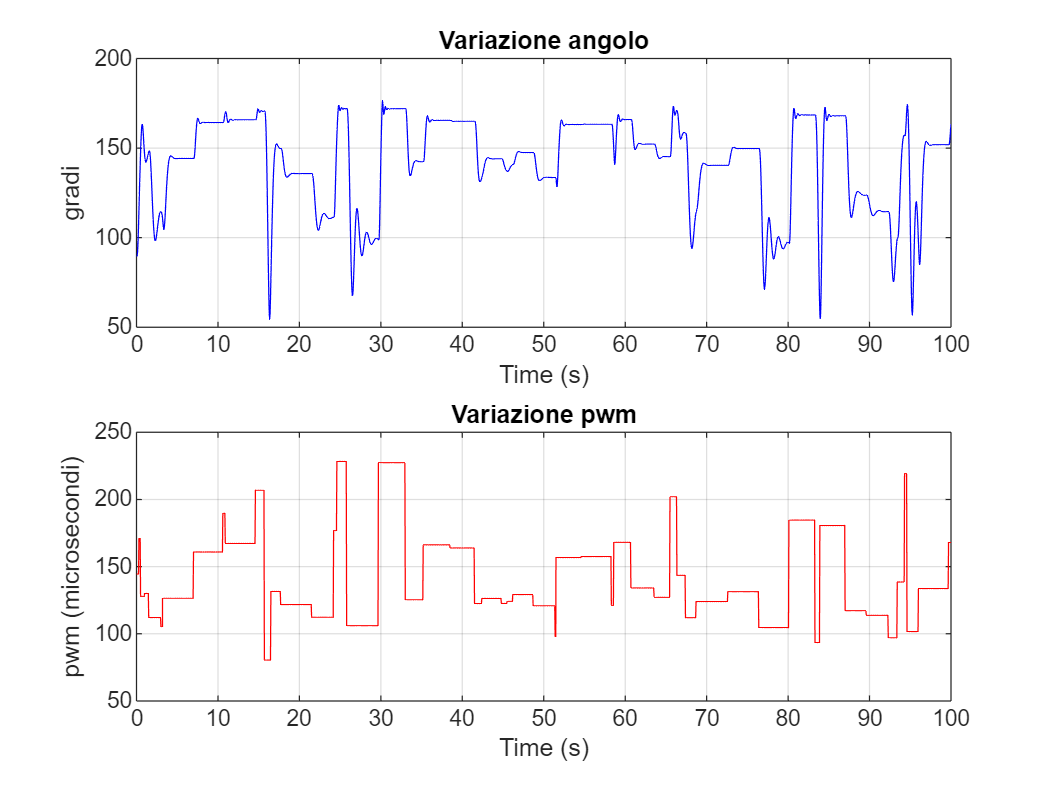

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
t = simulazione.time;

signal1 = simulazione.signals(1).values; % Primo segnale
signal2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal1, signal2, 'Variazione angolo', 'Variazione pwm');

% andiamo alla ricerca di un punto d'equilibrio in cui linearizzare il
% sistema: scegliamo la media del pwm.
pe=mean(pw); %Uso il valore medio come punto di equilibrio (157.1 gradi)
pe=pe*ones(2001, 1);   %Matrice di solo valore media da mettere nel simulatore

%cerchiamo un intorno del punto d'equilibrio.
upper_bound = 174.75; %pw
lower_bound = 128.755; %pw

caso1: rumore bianco

%adesso andiamo ad eccitare il sistema con più segnali di input.

%caso 1: RUMORE BIANCO
rb = lower_bound + (upper_bound - lower_bound) * rand(2001, 1);
input=[time,rb];
out2=sim("model.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso un rumore bianco (rb)
t = simulazione.time;

signal_rb1 = simulazione.signals(1).values; % Primo segnale
signal_rb2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_rb1, signal_rb2, 'Variazione angolo (rb)', 'Variazione pwm (rb)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;
[dati_rb_ide, dati_rb_val]=prepare_iddata(y, u, ts, 0.7)


dati_rb_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_rb_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)   

model_rb=armax(dati_rb_ide,[4 4 1 1]);
display(model_rb);


model_rb =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)         
  A(z) = 1 - 2.865 z^-1 + 3.275 z^-2 - 1.8 z^-3 + 0.4025 z^-4     
                                                                  
  B(z) = 0.001158 z^-1 + 0.0125 z^-2 + 0.01024 z^-3 - 0.01052 z^-4
                                                                  
  C(z) = 1 + 0.6174 z^-1                                          
                                                                  
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using ARMAX on time domain data "dati_rb_ide".
Fit to estimation data: 98.72% (prediction focus)       
FPE: 0.004598, MSE: 0.004514                            
 


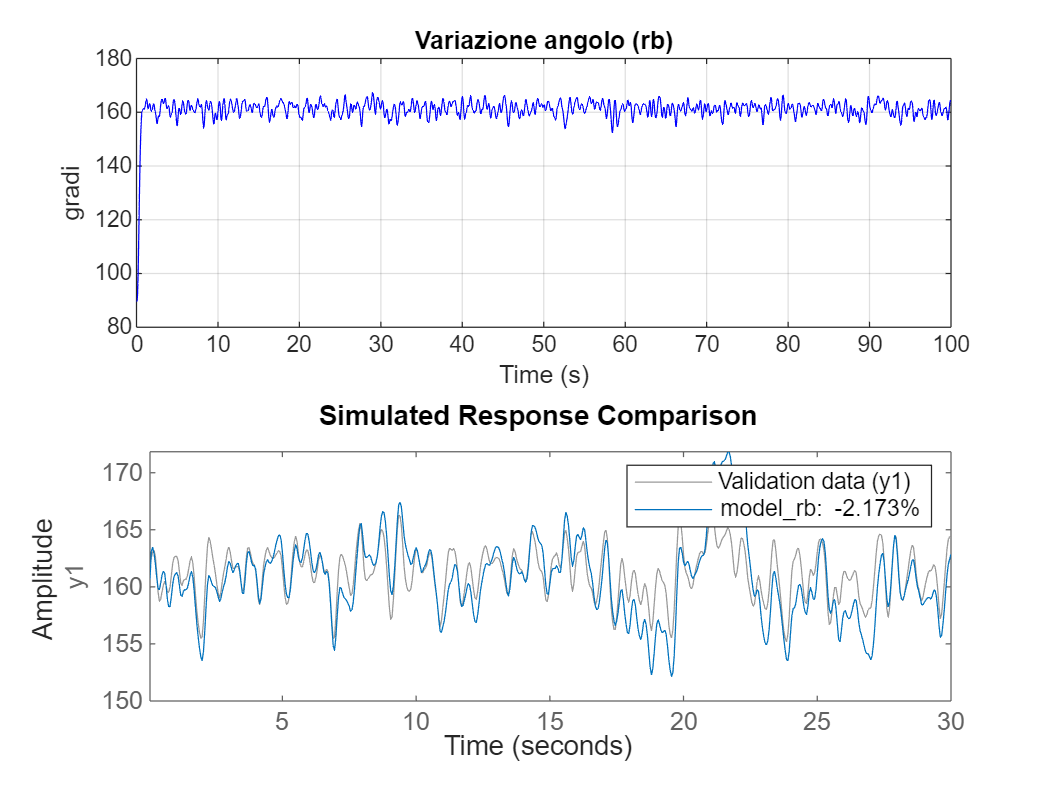

compare(dati_rb_val,model_rb)

caso2: sinusoide

% Adesso andiamo a eccitare il sistema con una sinusoide con ampiezza
% compresa fra l'intorno in cui vogliamo linearizzare il sistema.
amplitude = (upper_bound - lower_bound) / 2; % Ampiezza
offset = (upper_bound + lower_bound) / 2;   % Offset
% Parametri della sinusoide
frequency = 1;   % Frequenza in Hz
duration = 100;    % Durata totale in secondi
sampling_interval = 0.05; % Passo temporale in secondi
% Asse del tempo
durata = 0:sampling_interval:duration; % Campionamento a intervalli di 0.05 secondi
% Creazione della sinusoide
sinusoide = amplitude * sin(2 * pi * frequency * durata) + offset;
s=sinusoide';

input=[time,s];
out2=sim("model.mdl");

i = 1


%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso una sinusoide (s)
t = simulazione.time;

signal_s1 = simulazione.signals(1).values; % Primo segnale
signal_s2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_s1, signal_s2, 'Variazione angolo (sin)', 'Variazione pwm (sin)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;

[dati_s_ide,dati_s_val]=prepare_iddata(y, u, ts, 0.7)


dati_s_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_s_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
  

model_s=armax(dati_s_ide,[4 4 1 1]);
display(model_s);


model_s =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)      
  A(z) = 1 - 2.906 z^-1 + 3.659 z^-2 - 2.301 z^-3 + 0.6016 z^-4
                                                               
  B(z) = 0.185 z^-1 - 0.1659 z^-2 - 0.1381 z^-3 + 0.1753 z^-4  
                                                               
  C(z) = 1 + 0.9854 z^-1                                       
                                                               
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using ARMAX on time domain data "dati_s_ide".
Fit to estimation data: 99.3% (prediction focus)       
FPE: 0.003679, MSE: 0.003611                           
 


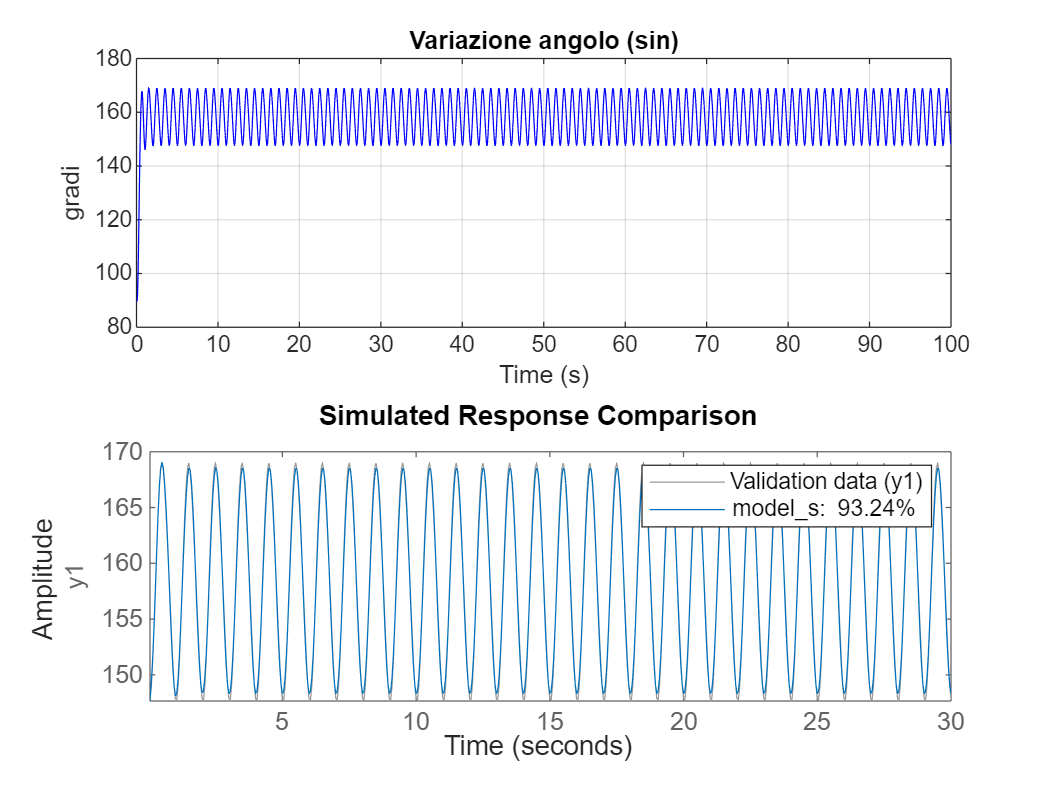

compare(dati_s_val,model_s);

% la sinusoide segue bene, ma perchè i dati di validazione sono alla
% medesima frequenza...proviamo a fargi seguire una sinusoide ad una f
% diversa.

nuova_s=amplitude * sin(2 * pi * (frequency +4 )* durata) + offset;
nuova_s=nuova_s';

%adesso eseguo il simulink avendo come input
input=[time,nuova_s];
out3=sim("model.mdl");

i = 1

[dati_prova_ide,dati_prova_val]=prepare_iddata(y, u, ts, 0.7)


dati_prova_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_prova_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       U

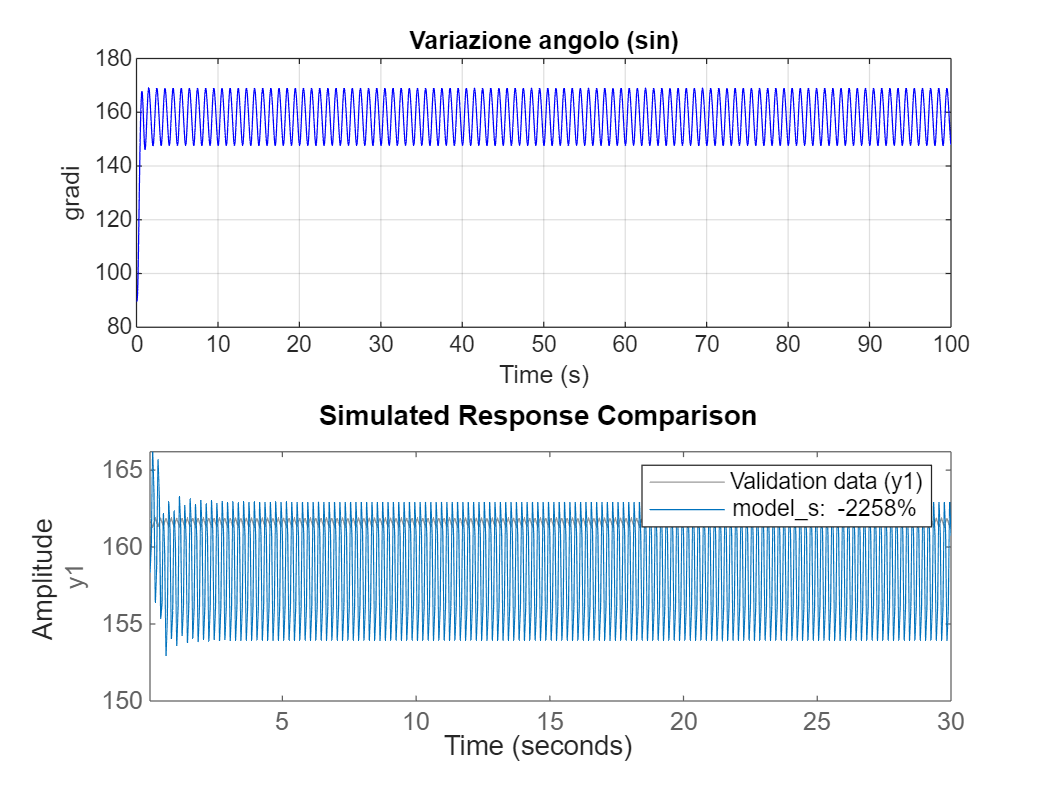

compare(dati_prova_val , model_s)

% dal grafico vediamo che la sinusoide si dimostra essere un pessimo
% ingresso per eccitare il sistema

caso3: PRBS (Pseudo-Random Binary Signal)

%andiamo adesso ad eccitare il sistema con il segnale PRBS.
amplitude = [lower_bound, upper_bound];
%creo il segnale
prbs = idinput(2001, 'prbs', [0 1], amplitude);

input=[time,prbs];
out4=sim("model.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso una sinusoide (s)
t = simulazione.time;

signal_prbs1 = simulazione.signals(1).values; % Primo segnale
signal_prbs2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_prbs1, signal_prbs2, 'Variazione angolo (prbs)', 'Variazione pwm (prbs)')
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;

[dati_prbs_ide,dati_prbs_val]=prepare_iddata(y, u, ts, 0.7)


dati_prbs_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_prbs_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if

model_prbs=armax(dati_prbs_ide,[4 4 1 1]);
display(model_prbs);


model_prbs =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)            
  A(z) = 1 - 3.154 z^-1 + 3.853 z^-2 - 2.19 z^-3 + 0.4898 z^-4       
                                                                     
  B(z) = 0.0009374 z^-1 + 0.01216 z^-2 + 0.006255 z^-3 - 0.01985 z^-4
                                                                     
  C(z) = 1 - 0.7551 z^-1                                             
                                                                     
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                   
Estimated using ARMAX on time domain data "dati_prbs_ide".
Fit to estimation data: 97.61% (prediction focus)         
FPE: 0.02611, MSE: 0.02563                                
 


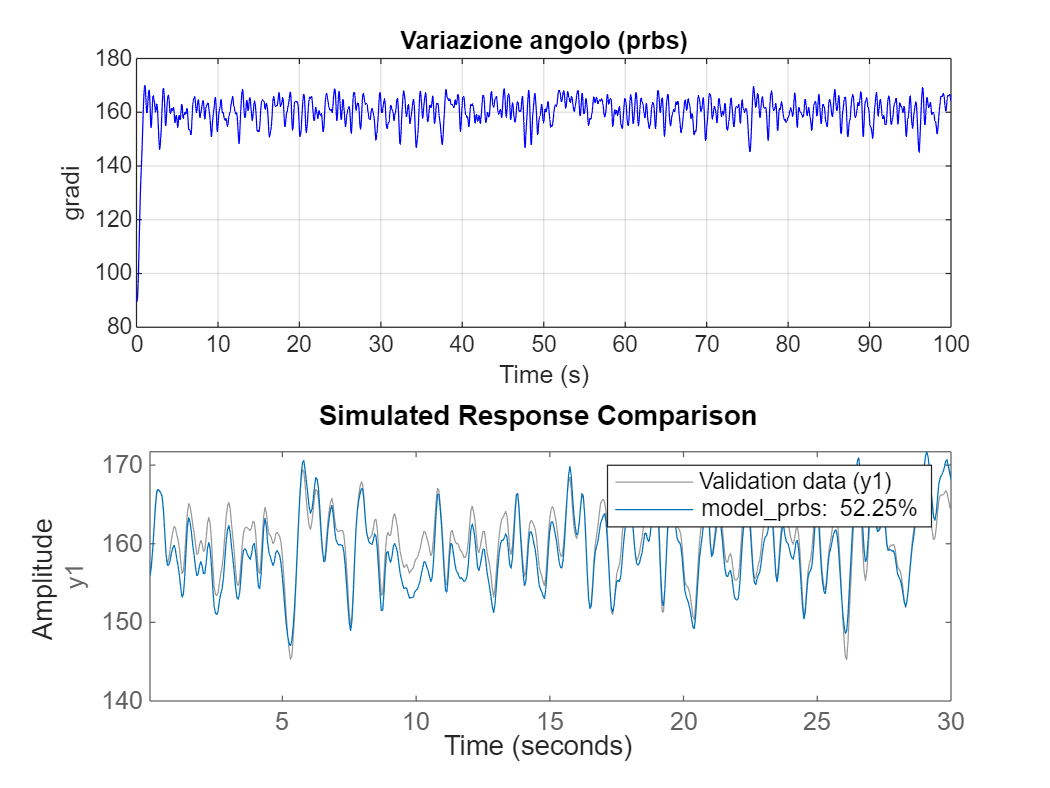

compare(dati_prbs_val,model_prbs);

caso 4: rumore bianco a blocchi di 30 valori costanti (rbb)

total_length = 2001;  % Lunghezza totale del segnale
block_size = 30;      % Dimensione di ciascun blocco
n_blocks = ceil(total_length / block_size);
block_values = lower_bound + (upper_bound - lower_bound) * rand(n_blocks, 1);
rbb = repelem(block_values, block_size);
rbb = rbb(1:total_length);
input=[time,rbb];
out5=sim("model.mdl");

i = 1

%stampo a video la variazione dell'angolo del ginocchio e quella del pwm
% avente per ingresso un rumore bianco a blocchi (rbb)
t = simulazione.time;

signal_rbb1 = simulazione.signals(1).values; % Primo segnale
signal_rbb2 = simulazione.signals(2).values; % Secondo segnale
plot_signals(t, signal_rbb1, signal_rbb2, 'Variazione angolo (rbb)', 'Variazione pwm (rbb)');
%Procedo all'identificazione del processo con il Sytem Identification toolbox
% stima:70% , validazione: 30%
ts=0.05;
[dati_rbb_ide, dati_rbb_val]=prepare_iddata(y, u, ts, 0.7)


dati_rbb_ide =

Time domain data set with 1401 samples.
Sample time: 0.05 seconds               
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties

dati_rbb_val =

Time domain data set with 600 samples.
Sample time: 0.05 seconds              
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specif

model_rbb=armax(dati_rbb_ide,[4 4 1 1]);
display(model_rbb);


model_rbb =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)            
  A(z) = 1 - 3.149 z^-1 + 3.803 z^-2 - 2.105 z^-3 + 0.4514 z^-4      
                                                                     
  B(z) = 0.0007354 z^-1 + 0.01243 z^-2 + 0.004846 z^-3 - 0.01797 z^-4
                                                                     
  C(z) = 1 + 0.8213 z^-1                                             
                                                                     
Sample time: 0.05 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=1   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using ARMAX on time domain data "dati_rbb_ide".
Fit to estimation data: 99.66% (prediction focus)        
FPE: 0.0005856, MSE: 0.0005748                           
 


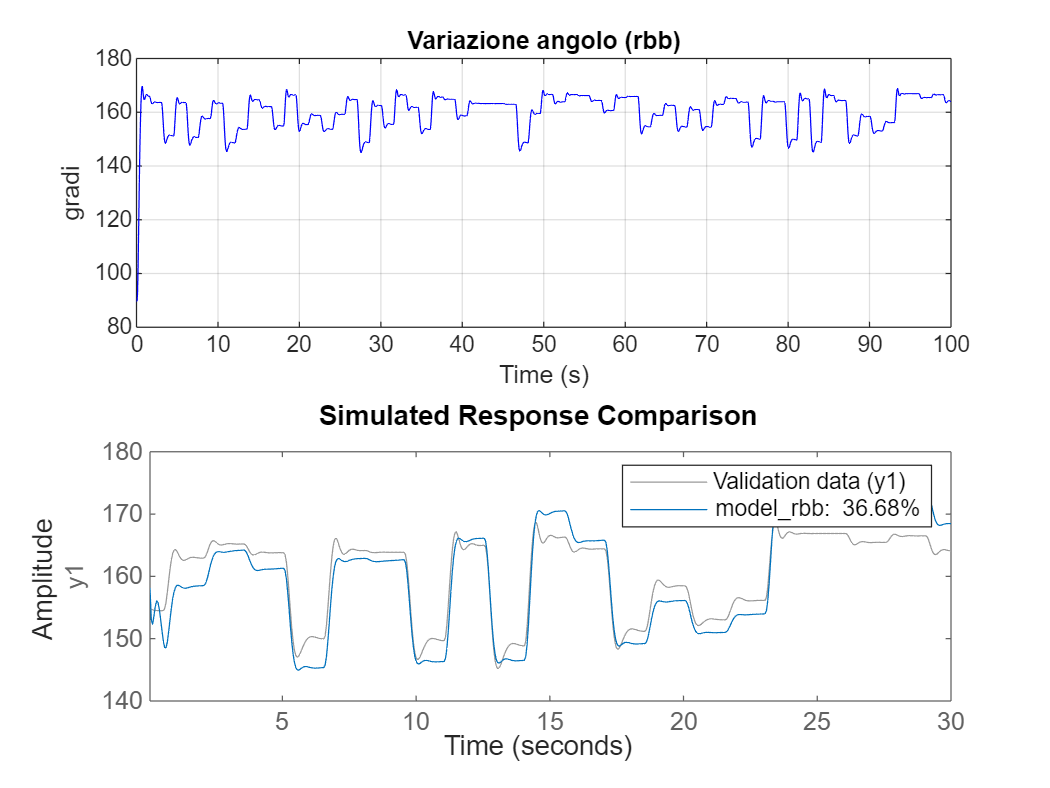

compare(dati_rbb_val,model_rbb)